## PMDC Motor without Controller(as matrix)

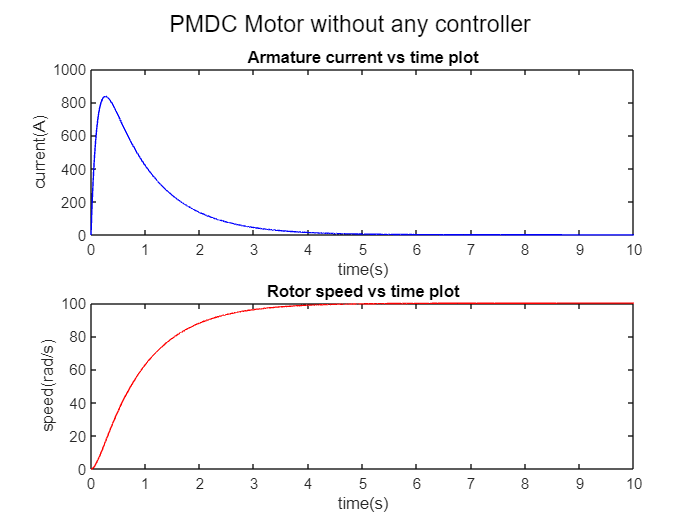

clear;
close;
t_end = 10;
dt = 1e-3;
t = 0:dt:t_end;
numS = length(t);
x = zeros(2,numS);
Vinput=100;
Tl=0;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
global A
A=[-(Ra/La) -(kb/La);(kt/J) (-B_w/J)];
global B
B=[1/La 0;0 -1/J];
f=@(t,x,input_voltage,torque_load) A*x+B*[input_voltage;torque_load];
x(:,1) = [0;0];
for i = 1:numS-1
    k_1 = dt*f(t(i),x(:,i),Vinput,Tl);
    k_2 = dt*f(t(i) + dt/2, x(:,i) + k_1/2,Vinput,Tl);
    k_3 = dt*f(t(i) + dt/2, x(:,i) + k_2/2,Vinput,Tl);
    k_4 = dt*f(t(i) + dt  , x(:,i) + k_3,Vinput,Tl);
    x(:,i+1) = x(:,i) + (k_1 + 2*k_2 + 2*k_3 + k_4)/6;
end
figure
hold on
sgtitle('PMDC Motor without any controller')
subplot(2,1,1)
plot(t,x(1,:),'b')
xlabel('time(s)')
ylabel('current(A)')
title('Armature current vs time plot')
subplot(2,1,2)
plot(t,x(2,:),'r')
xlabel('time(s)')
ylabel('speed(rad/s)')
title('Rotor speed vs time plot')
hold off

## PMDC Motor with single PID controller(no disturbance)

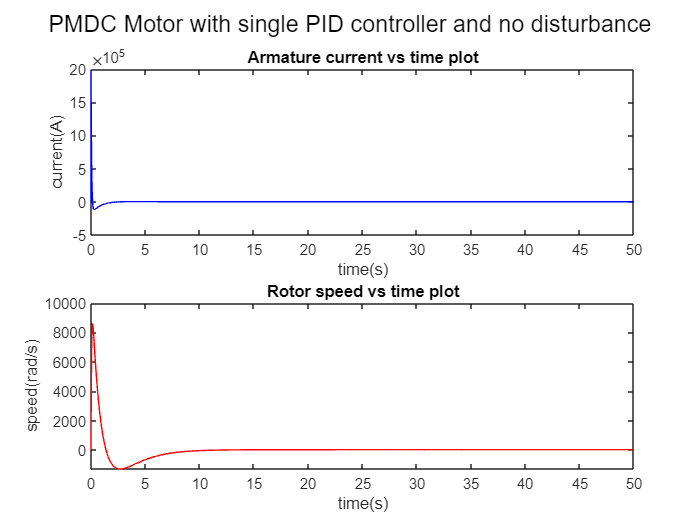

clc;
clear;
close;
t_end = 50;
dt = 1e-3;
t = 1e-6:dt:t_end;
numS = length(t);
x = zeros(2,numS);
Vinput=10;
Tl=0;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
wref=20;
global A
A=[-(Ra/La) -(kb/La);(kt/J) (-B_w/J)];
global B
B=[1/La 0;0 -1/J];
global tp ep I
ep=0;
I=0;
de=-x(2);
tp=0;
f=@(t,x,input_voltage,torque_load) A*x+B*[input_voltage;torque_load];
x(:,1) = [0;0];
for i = 1:numS-1
    e=wref-x(2,i);
    de=(e-ep)/(t(i)-tp);
    Vinput=control_one_loop(t(i),e,de,tp);
    k_1 = dt*f(t(i),x(:,i),Vinput,Tl);
    k_2 = dt*f(t(i) + dt/2, x(:,i) + k_1/2,Vinput,Tl);
    k_3 = dt*f(t(i) + dt/2, x(:,i) + k_2/2,Vinput,Tl);
    k_4 = dt*f(t(i) + dt  , x(:,i) + k_3,Vinput,Tl);
    x(:,i+1) = x(:,i) + (k_1 + 2*k_2 + 2*k_3 + k_4)/6;
    tp=t(i);
    ep=e;
end
figure
hold on
sgtitle('PMDC Motor with single PID controller and no disturbance')
subplot(2,1,1)
plot(t,x(1,:),'b')
xlabel('time(s)')
ylabel('current(A)')
title('Armature current vs time plot')
subplot(2,1,2)
plot(t,x(2,:),'r')
xlabel('time(s)')
ylabel('speed(rad/s)')
title('Rotor speed vs time plot')
hold off

## PMDC Motor with single PID controller(with torque disturbance)

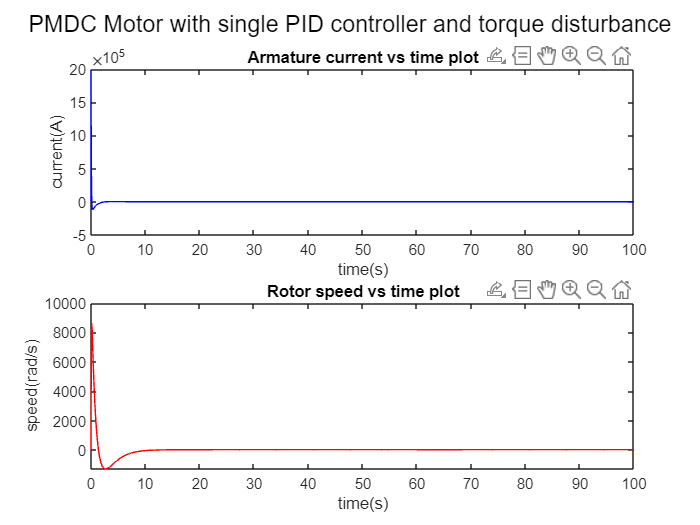

clc;
clear;
close;
t_end = 100;
dt = 1e-3;
t = 1e-6:dt:t_end;
numS = length(t);
x = zeros(2,numS);
%Vinput=10;
load_torque=100;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
wref=20;
global A
A=[-(Ra/La) -(kb/La);(kt/J) (-B_w/J)];
global B
B=[1/La 0;0 -1/J];
global tp ep I
ep=0;
I=0;
de=-x(2);
tp=0;
f=@(t,x,input_voltage,torque_load) A*x+B*[input_voltage;torque_load];
x(:,1) = [0;0];
for i = 1:numS-1
    e=wref-x(2,i);
    de=(e-ep)/(t(i)-tp);
    Vinput=control_one_loop(t(i),e,de,tp);
    %t(i)
    Tl(i)=load_torque * (t(i)>60 && t(i)<t_end);
    k_1 = dt*f(t(i),x(:,i),Vinput,Tl(i));
    k_2 = dt*f(t(i) + dt/2, x(:,i) + k_1/2,Vinput,Tl(i));
    k_3 = dt*f(t(i) + dt/2, x(:,i) + k_2/2,Vinput,Tl(i));
    k_4 = dt*f(t(i) + dt  , x(:,i) + k_3,Vinput,Tl(i));
    x(:,i+1) = x(:,i) + (k_1 + 2*k_2 + 2*k_3 + k_4)/6;
    tp=t(i);
    ep=e;
end
figure
hold on
sgtitle('PMDC Motor with single PID controller and torque disturbance')
subplot(2,1,1)
plot(t,x(1,:),'b')
xlabel('time(s)')
ylabel('current(A)')
title('Armature current vs time plot')
subplot(2,1,2)
plot(t,x(2,:),'r')
xlabel('time(s)')
ylabel('speed(rad/s)')
title('Rotor speed vs time plot')
hold off

## PMDC Motor with two PID controllers(without torque disturbance)-Outer slow speed loop and inner fast current loop

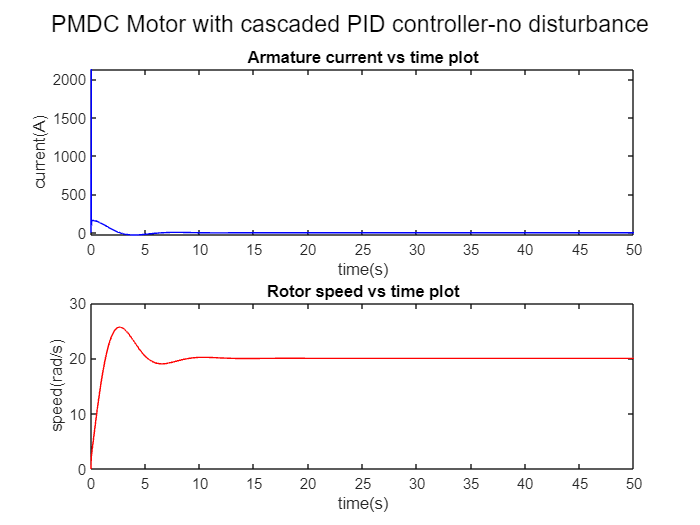

clc;
clear;
close;
t_end = 50;
dt = 1e-3;
t = 1e-6:dt:t_end;
numS = length(t);
x = zeros(2,numS);
load_torque=0;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
wref=20;
iaref=0;
global A
A=[-(Ra/La) -(kb/La);(kt/J) (-B_w/J)];
global B
B=[1/La 0;0 -1/J];
global tpia Iw Iia tpw
theta_ref=0.1;
epw=0;
Iw=0;
Iia=0;
epia=0;
de=-x(2);
tpia=0;
tpw=0;
f=@(t,x,input_voltage,torque_load) A*x+B*[input_voltage;torque_load];
x(:,1) = [0;0];
for i = 1:numS-1
    if(rem(i,10)==0)
    ew=wref-x(2,i);
    dew=(ew-epw)/(t(i)-tpw);
    iaref=speed_pid(t(i),tpw,ew,dew);
    tpw=t(i);
    epw=ew;
    end
    eia=iaref-x(1,i);
    deia=(eia-epia)/(t(i)-tpia);
    Vinput=current_pid(t(i),tpia,eia,epia);
    Tl(i)=0;
    k_1 = dt*f(t(i),x(:,i),Vinput,Tl(i));
    k_2 = dt*f(t(i) + dt/2, x(:,i) + k_1/2,Vinput,Tl(i));
    k_3 = dt*f(t(i) + dt/2, x(:,i) + k_2/2,Vinput,Tl(i));
    k_4 = dt*f(t(i) + dt  , x(:,i) + k_3,Vinput,Tl(i));
    x(:,i+1) = x(:,i) + (k_1 + 2*k_2 + 2*k_3 + k_4)/6;
    tpia=t(i);
    epia=eia;
end
figure
hold on
sgtitle('PMDC Motor with cascaded PID controller-no disturbance')
subplot(2,1,1)
plot(t,x(1,:),'b')
xlabel('time(s)')
ylabel('current(A)')
title('Armature current vs time plot')
subplot(2,1,2)
plot(t,x(2,:),'r')
xlabel('time(s)')
ylabel('speed(rad/s)')
title('Rotor speed vs time plot')
hold off

## PMDC Motor with two PID controllers(with torque disturbance)-Outer slow speed loop and inner fast current loop

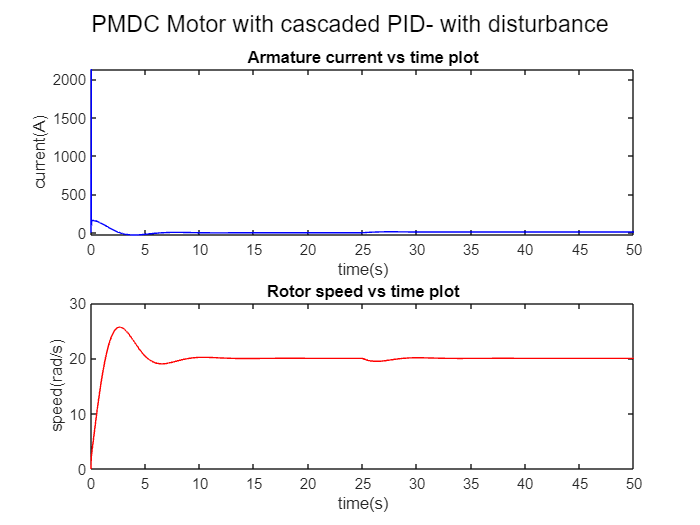

clc;
clear;
close;
t_end = 50;
dt = 1e-3;
t = 1e-6:dt:t_end;
numS = length(t);
x = zeros(2,numS);
load_torque=10;
La=0.01;
Ra=0.1;
J=10;
B_w=0.01;
kb=1;
kt=1;
wref=20;
iaref=0;
global A
A=[-(Ra/La) -(kb/La);(kt/J) (-B_w/J)];
global B
B=[1/La 0;0 -1/J];
global tpia Iw Iia tpw
epw=0;
Iw=0;
Iia=0;
epia=0;
de=-x(2);
tpia=0;
tpw=0;
f=@(t,x,input_voltage,torque_load) A*x+B*[input_voltage;torque_load];
x(:,1) = [0;0];
for i = 1:numS-1
    if(rem(i,10)==0)
    ew=wref-x(2,i);
    dew=(ew-epw)/(t(i)-tpw);
    iaref=speed_pid(t(i),tpw,ew,dew);
    tpw=t(i);
    epw=ew;
    end
    eia=iaref-x(1,i);
    deia=(eia-epia)/(t(i)-tpia);
    Vinput=current_pid(t(i),tpia,eia,epia);
    Tl(i)=load_torque *(t(i)>25 && t(i)<50);
    k_1 = dt*f(t(i),x(:,i),Vinput,Tl(i));
    k_2 = dt*f(t(i) + dt/2, x(:,i) + k_1/2,Vinput,Tl(i));
    k_3 = dt*f(t(i) + dt/2, x(:,i) + k_2/2,Vinput,Tl(i));
    k_4 = dt*f(t(i) + dt  , x(:,i) + k_3,Vinput,Tl(i));
    x(:,i+1) = x(:,i) + (k_1 + 2*k_2 + 2*k_3 + k_4)/6;
    tpia=t(i);
    epia=eia;
end
figure
hold on
sgtitle('PMDC Motor with cascaded PID- with disturbance')
subplot(2,1,1)
plot(t,x(1,:),'b')
xlabel('time(s)')
ylabel('current(A)')
title('Armature current vs time plot')
subplot(2,1,2)
plot(t,x(2,:),'r')
xlabel('time(s)')
ylabel('speed(rad/s)')
title('Rotor speed vs time plot')
hold off

function u=control_one_loop(tt,e,de,ttp)
kp=2;
ki=1;
kd=1;
global I;
I=(I+ki*e*(tt-ttp));
u=kp*e+I+kd*de;
end


function iref=speed_pid(tt,ttp,e,de)
global Iw;
kp=10;
ki=10;
kd=1;
Iw=(Iw+ki*e*(tt-ttp));
iref=kp*e+Iw+kd*de;
end

function u=current_pid(tt,ttp,e,de)
global Iia;
kp=1;
ki=1;
kd=1;
Iia=(Iia+ki*e*(tt-ttp));
u=kp*e+Iia+kd*de;
end